% initialize
setup
addpath(genpath('C:\Users\adalca\Dropbox (Personal)\MATLAB\external_toolboxes\view3D'));

Setup parameters

atlPatchSize = ones(1, 3) * 9;  
atlLoc = LOC_VENTRICLE_EDGE; %LOC_VENTRICLE_EDGE; % LOC_LEFT_CORTEX+10; %LOC_VENTRICLE_EDGE; %LOC_LEFT_CORTEX;
atlLoc = [52,43,34];
atlLoc = [67,75,89]; % midsaggital
% atlPatchSize = ones(1, 3) * 6; 
% atlLoc = [69, 51, 43]; % scale 3
% atlLoc = [53, 48, 48];
% 
% atlPatchSize = ones(1, 3) * 5;
% atlLoc = [20, 25, 35];
% atlLoc = [22, 20, 20]*2;

gmmK = 5; % 5 good for ventricle, 25 for cortex?
crmethod = 'inverse'; % 'forward', 'inverse'
regVal = 1e-4; % regulaization to the diagonal of subjSigma, if using method forward
reconSubj = 7; %1, 3
patchColPad = ones(1, 3) * 2;

% train and test datasets
traindataset = 'adni';
testdataset = 'adni';

% recon params
keepr = 1;
subvolLoc = atlLoc - patchColPad;
subvolSize = atlPatchSize + (2 * patchColPad);

% modalities
ds = 5;
us = 5;
% isoSubjInAtlMod = sprintf('brainIso2Ds%dUs%dsizeReg', ds, us);
% dsSubjInAtlMod = sprintf('brainIso2Ds%dUs%dsize_Ds2Us2Reg', ds, us);
% dsSubjInAtlMaskMod = sprintf('brainIso2Ds%dUs%dsize_Ds2Us2MaskReg', ds, us);
% dsSubjInAtlMatMod = sprintf('brainDs%dUs%dRegMat', ds, ds); % note: meant to be ds, ds !
% dsInterpSubjInAtlMod = sprintf('brainDs%dUs%dInterpReg', ds, us);
% 
% dsSubjMod = sprintf('brainIso2Ds%dUs%dsize_Ds2Us2', ds, us);
% dsSubjMaskMod = sprintf('brainIso2Ds%dUs%dsize_Ds2Us2Mask', ds, us);
% isoSubjMod = sprintf('brainIso2Ds%dUs%dsize', ds, us);


isoSubjInAtlMod = sprintf('brainIso2Ds%dUs%dsizeReg', ds, us);
dsSubjInAtlMod = sprintf('brainDs%dUs%dReg', ds, us);
dsSubjInAtlMaskMod = sprintf('brainDs%dUs%dRegMask', ds, us);
dsSubjInAtlMatMod = sprintf('brainDs%dUs%dRegMat', ds, ds); % note: meant to be ds, ds !
dsInterpSubjInAtlMod = sprintf('brainDs%dUs%dInterpReg', ds, us);

dsSubjMod = sprintf('brainDs%dUs%d', ds, us);
dsSubjMaskMod = sprintf('brainDs%dUs%dMask', ds, us);
isoSubjMod = sprintf('brainIso2Ds%dUs%dsize', ds, us);


%% load buckner volumes and prepare volume data
% load ADNI full-subject, and buckner full-dataset column.

% load various data columns from training set
fnames = fullfile(SYNTHESIS_DATA_PATH, traindataset, 'md', [sys.usrname, '_restor_md_*']);
trainmd = loadmd(fnames);
[bucknerIsoPatchCol, layeridx, volidx] = ...
    subspacetools.md2patchcol(trainmd, isoSubjInAtlMod, atlPatchSize, atlLoc, patchColPad);
[bucknerDsPatchCol, ~, ~] = ...
    subspacetools.md2patchcol(trainmd, dsSubjInAtlMod, atlPatchSize, atlLoc, patchColPad);
[bucknerDsMaskPatchCol, ~, ~] = ...
    subspacetools.md2patchcol(trainmd, dsSubjInAtlMaskMod, atlPatchSize, atlLoc, patchColPad);


% load selected ADNI subject volumes
fnames = fullfile(SYNTHESIS_DATA_PATH, testdataset, 'md', [sys.usrname, '_restor_md_*']);
testmd = loadmd(fnames);
dsSubjNii = testmd.loadModality(dsSubjMod, reconSubj);
dsSubjVol = double(dsSubjNii.img);
dsSubjWeightVol = logical(testmd.loadVolume(dsSubjMaskMod, reconSubj));
dsSubjInAtlNii = testmd.loadModality(dsSubjInAtlMod, reconSubj);
dsSubjInAtlMaskVol = testmd.loadVolume(dsSubjInAtlMaskMod, reconSubj);
subjInAtlTform = load(testmd.getModality(dsSubjInAtlMatMod, reconSubj));

% prepare necessary inputs for conditional-based reconstruction
subjDims = dsSubjNii.hdr.dime.pixdim(2:4);
atlDims = dsSubjInAtlNii.hdr.dime.pixdim(2:4);
tform = subjInAtlTform.tform;
atlVolSize = size(dsSubjInAtlNii.img);
subjLoc2AtlSpace = tform2cor3d(tform, size(dsSubjVol), subjDims, atlVolSize, atlDims);
atlLoc2SubjSpace = tform2cor3d(tform, size(dsSubjVol), subjDims, atlVolSize, atlDims, 'backward');
extraReconArg = ifelse(strcmp(crmethod, 'inverse'), subjLoc2AtlSpace, regVal);


%% learn a gmm
gmmopt = statset('Display', 'iter', 'MaxIter', 20, 'TolFun', 0.001);

% compute the gaussian mixture model. TODO: should use wgmmfit with model0
tic
X = bsxfun(@minus, bucknerIsoPatchCol, mean(bucknerIsoPatchCol, 2));
gmdistIso = fitgmdist(X, gmmK, 'regularizationValue', regVal, 'replicates', 3, 'Options', gmmopt);


Repetition: 1
  iter	    log-likelihood
     1	 7.11677e+07
     2	 2.42344e+08
     3	 2.43192e+08
     4	 2.43402e+08
4 iterations, log-likelihood = 2.43402e+08

Repetition: 2
  iter	    log-likelihood
     1	 8.75871e+07
     2	 2.41829e+08
     3	 2.42164e+08
     4	 2.42473e+08
     5	 2.42834e+08
     6	 2.43134e+08
     7	 2.43248e+08
7 iterations, log-likelihood = 2.43248e+08

Repetition: 3
  iter	    log-likelihood
     1	 8.19138e+07
     2	 2.42181e+08
     3	 2.43167e+08
     4	 2.43382e+08
4 iterations, log-likelihood = 2.43382e+08


fprintf('gmm took %3.3f sec\n', toc);

gmm took 356.089 sec


gmmIso = wgmm.gmdist2wgmm(gmdistIso);

isopost = gmdistIso.posterior(X);
[~, mi] = max(isopost, [], 2);


%% D models
dfn = @(w) diag((w<0.5)*1000000000);
dfn = @(w) diag(-log(w+eps)*100000000);
dfn = @(w) diag(0.0001*(exp(-10*(w-1)) - 0.99));

% load('D:\Dropbox (MIT)\Research\patchSynthesis\adrianpatches2');
dsPatches = bucknerDsPatchCol;
wtPatches = bucknerDsMaskPatchCol;
subvolLoc = atlLoc - patchColPad;

threshold = 0.5;
minNonNan = 50;
% mi = clusterIdx;
settings = {[1000, 10, 0.01], [5000, 10, 0.001], [5000, 2, 0.001], [5000, 10, 0.01], [2500, 10, 0.01]};
settings = {[5000, 10, 0.005]};
[N, D] = size(dsPatches);

for zi = 1:numel(settings)
    ecmtic = tic;
    nSampl = settings{zi}(1);
    maxIter = settings{zi}(2);
    tol = settings{zi}(3);
    fprintf('Starting settings %d: [%d, %d, %f]\n', zi, nSampl, maxIter, tol);
    
    means = zeros(gmmK, D);
    sigmas = zeros(D, D, gmmK);
    for k = 1:gmmK
        f = find(mi == k);
        
        % get isotropic mu, sigma and sample if necessary
        X0 = dsPatches(f, :); X0 = bsxfun(@minus, X0, mean(X0, 2));
        W = wtPatches(f, :);
        if numel(f) > nSampl
            r = randsample(numel(f), nSampl);
            X0 = X0(r, :);
            W = W(r, :);
        end
        X0(W < threshold) = nan; % get nans
        % make sure we don't have too many nans
        [~, widx] = sort(W, 'descend');
        inds = sub2ind([size(W,1), D], widx(1:minNonNan,:), ndgrid(1:D, 1:minNonNan)'); 
        X0(inds(:)) = X0(inds(:));
        
        % estimate mean and sigmas with ECM algorithm.
        tic;
        [means(k, :), sigmas(:,:,k)] = ecmnmlex(X0, 'twostage', maxIter, tol); 
        fprintf('cluster %d done in %5.3fs\n', k, toc);
    end
    ecmtoc = toc(ecmtic); 

    wgt = wgmm(means, sigmas + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
    [qsel, reconLoc, cntvol] = papago.subvolRecon(wgt, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
        dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

    datasave(zi).wgt = wgt;
    datasave(zi).qsel = qsel;
    datasave(zi).nSampl = nSampl;
    datasave(zi).maxIter = maxIter;
    datasave(zi).tol = tol;
    datasave(zi).ecmtoc = ecmtoc;
    fprintf('Done settings %d: [%d, %d, %f]\n%s\n\n', zi, nSampl, maxIter, tol, repmat('-', [1, 80]));
end

Starting settings 1: [5000, 10, 0.005000]


-2271026.749589 0.012424 0.080092
-2327233.897483 0.004006 0.024447


cluster 1 done in 141.111s


-2588740.768182 0.012940 0.084622
-2650496.006142 0.003842 0.023574


cluster 2 done in 132.289s


-2432109.533378 0.011632 0.074212
-2486784.374765 0.003672 0.022231


cluster 3 done in 123.723s


-2166864.186641 0.013108 0.084453
-2225794.499323 0.004404 0.026831


cluster 4 done in 134.126s


-2303452.727475 0.012133 0.077662
-2359008.886859 0.003926 0.023831


cluster 5 done in 124.829s


Done settings 1: [5000, 10, 0.005000]
--------------------------------------------------------------------------------



Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn



Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn



Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn



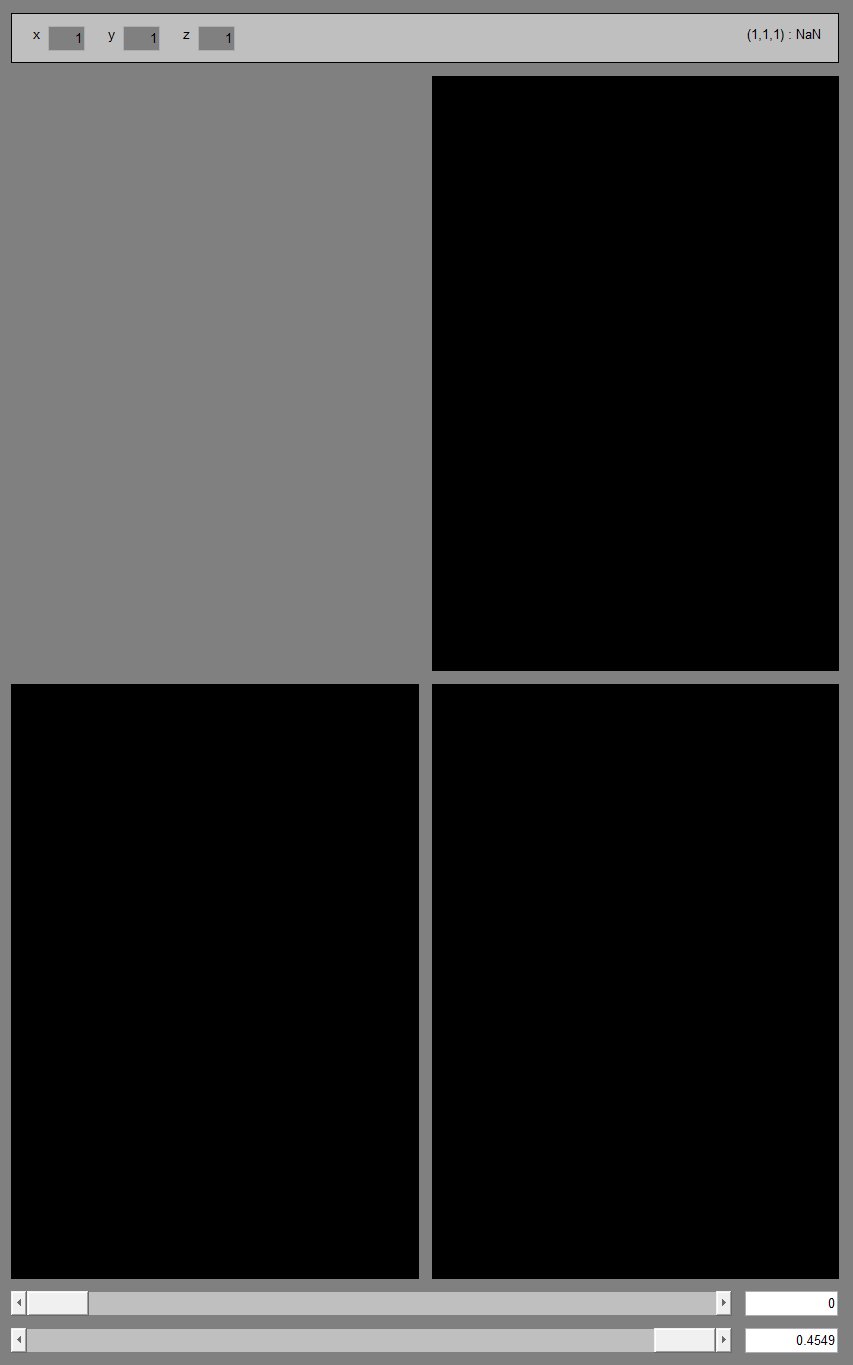

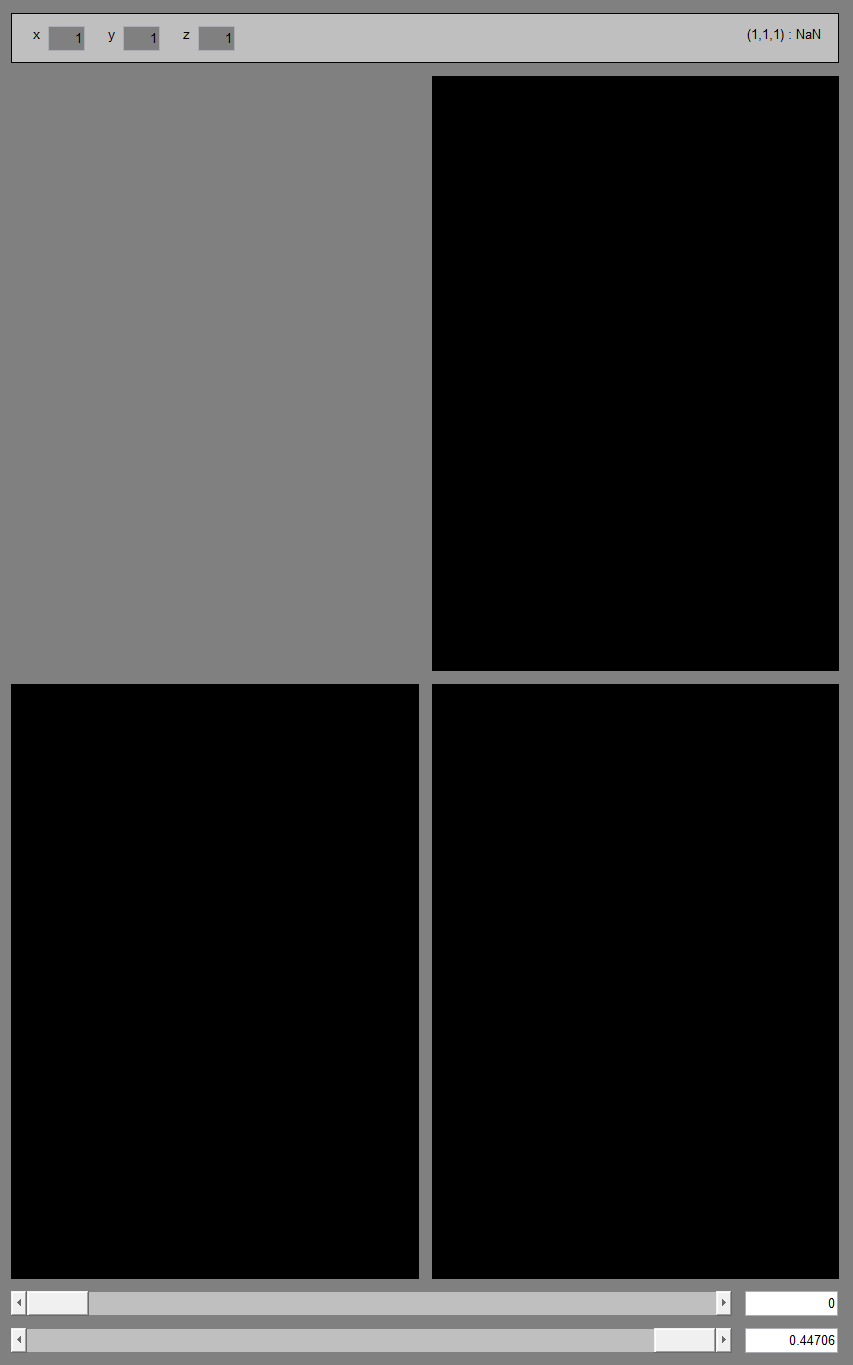

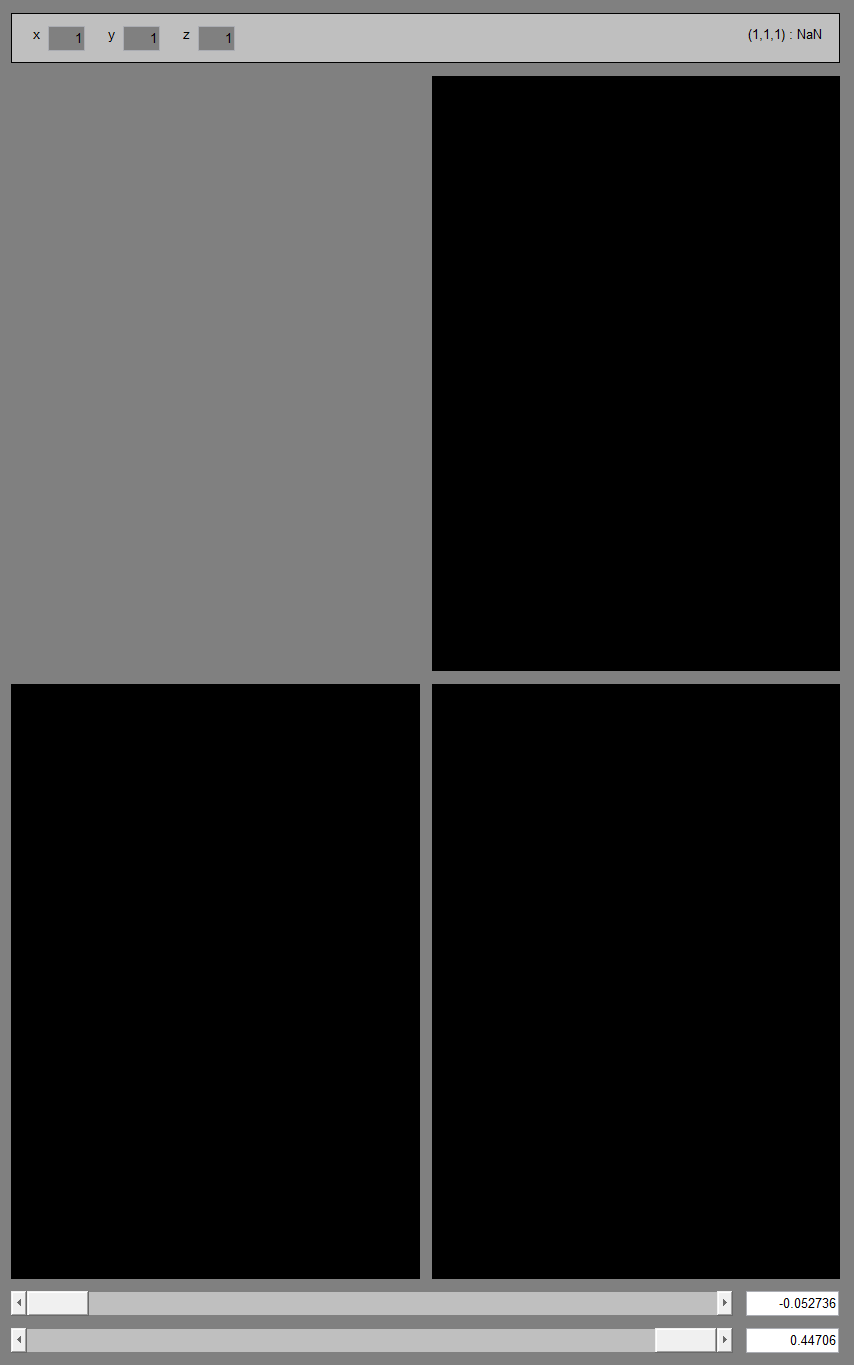


isoSubjVol = testmd.loadVolume(isoSubjMod, reconSubj);
cropIsoSubjVol = cropVolume(isoSubjVol, reconLoc, reconLoc + size(qsel) - 1); 
cropIsoSubjVol(isnan(qsel)) = nan;

% get linearly-interpolated data
dsSubjVolWNans = dsSubjVol;
cropDsSubjVolWNans = cropVolume(dsSubjVolWNans, reconLoc, reconLoc + size(qsel) - 1); 
cropDsSubjVolWNans(isnan(qsel)) = nan;

% get subject weight
subjWeightVolWNans = dsSubjWeightVol*1;
cropSubjWeightVolWNans = cropVolume(subjWeightVolWNans, reconLoc, reconLoc + size(qsel) - 1); 
cropSubjWeightVolWNans(isnan(qsel)) = nan;

qsels = {datasave.qsel};
view3Dopt(cropIsoSubjVol, cropDsSubjVolWNans, qsels{:});


for i = 1:numel(settings), 
    fprintf('nSampl:%2d MaxIter:%2d tol:%5.3f time:%5.3fsec\n', ...
        datasave(i).nSampl, datasave(i).maxIter, datasave(i).tol, datasave(i).ecmtoc); 
end

nSampl:5000 MaxIter:10 tol:0.005 time:658.824sec


%%
for i = 1:numel(settings), 
    [qsels{i}, reconLoc, cntvol] = papago.subvolRecon(datasave(i).wgt, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
        dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);
end



%% 
threshold = 0.5;
nSampl = 2500;
clear sigmast meanst sigmas0 means0 sigmas means means_iso sigmas_iso
for k = 1:gmmK

    % get isotropic mu, sigma
    X = bucknerIsoPatchCol(mi == k, :); X = bsxfun(@minus, X, mean(X, 2));
    X0 = bucknerDsPatchCol(mi == k, :); X0 = bsxfun(@minus, X0, mean(X0, 2));
    W = bucknerDsMaskPatchCol(mi == k, :);
    
    f = find(mi==k);
    if numel(f) > nSampl
        r = randsample(numel(f), nSampl);
        X0 = X0(r, :);
        W = W(r, :);
        X = X(r, :);
    end
    
    % basic stats from iso and ds data
%     sigmast(:,:,k) = cov(X); meanst(k, :) = mean(X);    
%     sigmas0(:,:,k) = cov(X0); means0(k, :) = mean(X0);
    
    % set up downsampled data with nans in any region with W < thr
    X0(W<threshold) = nan;
    % estimate mean and sigmas with ECM algorithm.
    tic;
    [means(k, :), sigmas(:,:,k)] = ecmnmlex(X0, 'twostage', 2, 0.001); 
    fprintf('cluster %d done in %5.3fs\n', k, toc);
    
%     tic;
%     X(W<threshold) = nan;
%     [means_iso(k, :), sigmas_iso(:,:,k)] = ecmnmlex(X, 'twostage', 5, 0.000); 
%     fprintf('cluster %d done in %5.3fs\n', k, toc);
    
%     imagesc([sigmas_iso(:,:,k), wgs{k}.sigma(:,:,1), sigmas_iso(:,:,k) - wgs{k}.sigma(:,:,1)])
%     drawnow;

%     % set up downsampled data with nans in any region with W < 0.75
%     X0tmp = X0; 
%     Xtmp = X; 
%     X0tmp(W<threshold) = nan;
%     Xtmp(W<threshold) = nan; 
%     
%     
%     hackNum = 50; 
%     [Wvals, idxWvals] = sort(W, 'descend'); 
%     nanColumns = sum(~isnan(X0tmp),1) < hackNum; 
%     colVals = find(nanColumns) ; 
%     inds = sub2ind( size(X0tmp),  idxWvals(1:hackNum, nanColumns), repmat(colVals, [hackNum, 1]) ); 
%     X0tmp( inds(:) ) = X0( inds(:) ); 
%     Xtmp( inds(:) ) = X( inds(:) ); 
%     
%     [means(k, :), sigmas(:,:,k)] = ecmnmlex(X0tmp, 'twostage', 10, 0.001);
end

wgt = wgmm(means, sigmas + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
[qsel, reconLoc, cntvol] = papago.subvolRecon(wgt, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
    dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

isoSubjVol = testmd.loadVolume(isoSubjMod, reconSubj);
cropIsoSubjVol = cropVolume(isoSubjVol, reconLoc, reconLoc + size(qsel) - 1); 
cropIsoSubjVol(isnan(qsel)) = nan;

% get linearly-interpolated data
dsSubjVolWNans = dsSubjVol;
cropDsSubjVolWNans = cropVolume(dsSubjVolWNans, reconLoc, reconLoc + size(qsel) - 1); 
cropDsSubjVolWNans(isnan(qsel)) = nan;

% get subject weight
subjWeightVolWNans = dsSubjWeightVol*1;
cropSubjWeightVolWNans = cropVolume(subjWeightVolWNans, reconLoc, reconLoc + size(qsel) - 1); 
cropSubjWeightVolWNans(isnan(qsel)) = nan;

view3Dopt(cropIsoSubjVol, cropDsSubjVolWNans, qsel);


%% Try cluster on ds exercise
maxOuterIter = 5;
threshold = 0.5; % TODO: 0.75 seemed better on ds5us2. test?
gmmopt = statset('Display', 'final', 'MaxIter', 20, 'TolFun', 0.001);

xbaro = bucknerDsPatchCol; xbaro = bsxfun(@minus, xbaro, mean(xbaro, 2));
xbar = xbaro;

thrvec = linspace(0.5, 0.75, maxOuterIter);
% thrvec = ones(1, maxOuterIter) * 0.5;
for j = 1:maxOuterIter
    
    threshold = thrvec(j);
    clear Z0 means sigmas
    
    % compute the gaussian mixture model. TODO: should use wgmmfit with model0
    tic
    gmdistDs = fitgmdist(xbar, gmmK, 'regularizationValue', regVal, 'replicates', 3, 'Options', gmmopt);
    fprintf('gmm took %3.3f sec\n', toc);
    dspost = gmdistDs.posterior(xbar);
    [~, mi] = max(dspost, [], 2);
    h = hist(mi, 1:gmmK)

    for k = 1:gmmK
        
        % get data
        X0 = xbar(mi == k, :);
        X0orig = X0;
        
        % check if there's enough data.
        if sum(mi == k) < 500
            fprintf(2, 'skipping cluster %d because it only has %d patches.', k, sum(mi == k));
            means{k} = mean(X0orig)';
            sigmas{k} = cov(X0orig);
            Z0{k} = X0orig;
            continue;
        end
        
        % estimate mean and sigmas with ECM algorithm.
        tic;
        W = bucknerDsMaskPatchCol(mi == k, :);
        % X0(W<threshold) = nan;
        p = zeros(size(X0, 1), 1);
        for ii = 1:size(X0, 1)
            w = W(ii, :);
            p(ii) = prctile(w, threshold*100);
            X0(ii, w < p(ii)) = nan;
        end
        
        [means{k}, sigmas{k}, Z0{k}] = ecmnmlex(X0, 'twostage', 20, 0.001, [], [], true); 
        assert(isclean(Z0{k}), 'Z0 is not clean:(')
        fprintf('cluster %d done in %5.3fs\n', k, toc);
    end
    
    xbar = cat(1, Z0{:});
    assert(isclean(xbar))
    estimates{j} = {cat(2, means{:})', cat(3, sigmas{:})};
end

% TODO: reconstruct from each j estimate!

for j = 1:maxOuterIter
    mu = reshape(estimates{j}{1}, [125, 5])';
    wgt = wgmm(mu, estimates{j}{2} + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
    [quiltedSubvolOuter{j}, reconLoc, cntvol] = papago.subvolRecon(wgt, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
        dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);
end
    
view3Dopt(cropDsSubjVolWNans, quiltedSubvolOuter{:})


%%

for k = 1:gmmK
    

    tic;
    wgs{k} = wgmmfit(X0, W, 1, 'model4fn', dfn,  'replicates', 1, 'initmethod', 'model4exp05', 'regularizationValue', 0, 'TolFun', -inf, 'MaxIter', 5);
    fprintf('wgmm cluster %d done in %5.3fs\n', k, toc);
    
    tic;
    wgs_iso{k} = wgmmfit(X, W, 1, 'model4fn', dfn,  'replicates', 1, 'initmethod', 'model4exp05', 'regularizationValue', 0, 'TolFun', -inf, 'MaxIter', 5);
    fprintf('wgmm cluster %d done in %5.3fs\n', k, toc);
    
    
    wgmm_m4ds_means(k, :) = wgs{k}.mu;
    wgmm_m4ds_sigmas(:, :, k) = wgs{k}.sigma;
    
    wgmm_m4iso_means(k, :) = wgs{k}.mu;
    wgmm_m4iso_sigmas(:, :, k) = wgs{k}.sigma;
end



%% setup wgmms
wgt = wgmm(meanst, sigmast + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
wg0 = wgmm(means0, sigmas0 + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
wg = wgmm(means, sigmas + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
wg_iso = wgmm(means_iso, sigmas_iso + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
wg_m4ds = wgmm(wgmm_m4ds_means, wgmm_m4ds_sigmas + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));
wg_m4iso = wgmm(wgmm_m4iso_means, wgmm_m4iso_sigmas + repmat(eye(size(X,2))*0.00001, [1,1,gmmK]), hist(mi, 1:gmmK)./sum(mi));


%% 

% reconstruct 
[quiltedSubvolt_k5, reconLoc, cntvol] = papago.subvolRecon(wgt, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
    dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

[quiltedSubvol0_k5, reconLoc, cntvol] = papago.subvolRecon(wg0, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
    dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

[quiltedSubvol_k5, reconLoc, cntvol] = papago.subvolRecon(wg, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
    dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

[quiltedSubvol_iso_k5, reconLoc, cntvol] = papago.subvolRecon(wg_iso, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
    dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

[quiltedSubvol_m4ds_k5, reconLoc, cntvol] = papago.subvolRecon(wg_m4ds, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
    dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

[quiltedSubvol_m4iso_k5, reconLoc, cntvol] = papago.subvolRecon(wg_m4iso, subvolLoc, subvolSize, atlPatchSize, crmethod, keepr, ...
    dsSubjInAtlNii.img, dsSubjInAtlMaskVol, dsSubjVol, dsSubjWeightVol, atlLoc2SubjSpace, extraReconArg);

view3Dopt(quiltedSubvolt_k5, quiltedSubvol0_k5, quiltedSubvol_iso_k5, quiltedSubvol_k5, quiltedSubvol_m4ds_k5, quiltedSubvol_m4iso_k5)


%%
qsel = quiltedSubvolOuter{1};
isoSubjVol = testmd.loadVolume(isoSubjMod, reconSubj);
cropIsoSubjVol = cropVolume(isoSubjVol, reconLoc, reconLoc + size(qsel) - 1); 
cropIsoSubjVol(isnan(qsel)) = nan;

% get linearly-interpolated data
dsSubjVolWNans = dsSubjVol;
cropDsSubjVolWNans = cropVolume(dsSubjVolWNans, reconLoc, reconLoc + size(qsel) - 1); 
cropDsSubjVolWNans(isnan(qsel)) = nan;

% get subject weight
subjWeightVolWNans = dsSubjWeightVol*1;
cropSubjWeightVolWNans = cropVolume(subjWeightVolWNans, reconLoc, reconLoc + size(qsel) - 1); 
cropSubjWeightVolWNans(isnan(qsel)) = nan;

view3Dopt(cropIsoSubjVol, cropDsSubjVolWNans, cropSubjWeightVolWNans, quiltedSubvolt_k5, quiltedSubvol0_k5, quiltedSubvol_k5)


